# Непрерывный вейвлет-анализ

Данный скрипт использует ядро **MATLAB, Signal Processing Toolbox **и** Wavelet Toolbox**

### **Загрузка и визуализация данных землетрясения:**

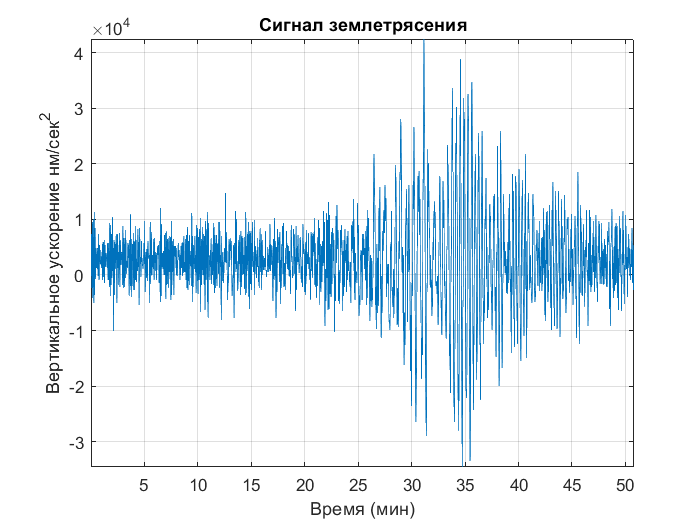

load eqData; figure;
plot(t,kobe);grid;
xlabel('Время (мин)');
ylabel('Вертикальное ускорение нм/сек^2');
title('Сигнал землетрясения');axis tight

### Частотно-временной анализ методом спектрограммы

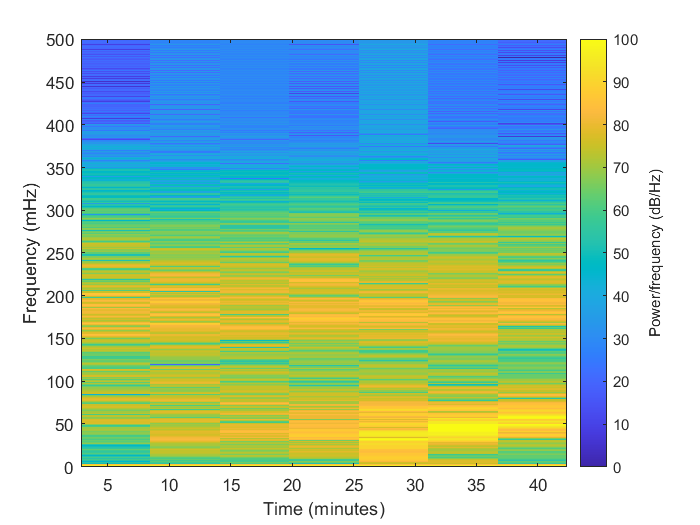

close all;
figure;
spectrogram(kobe,[],[],[],Fs,'yaxis');
caxis([0 100])

### Спектрограмма с коротким окном

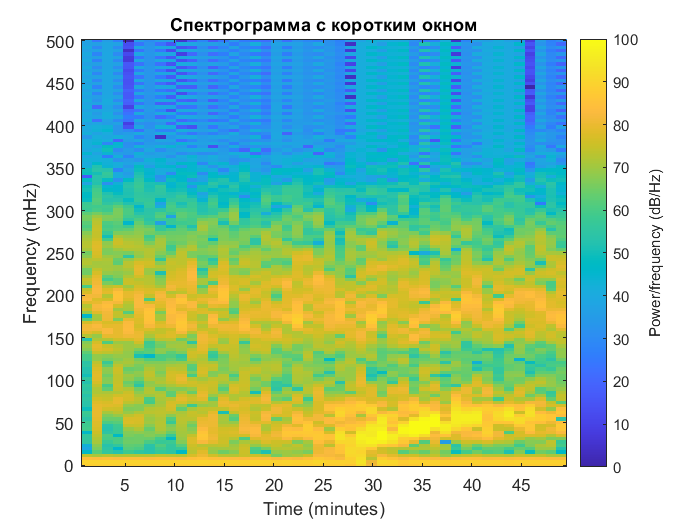

figure; 
spectrogram(kobe,128,[],[],Fs,'yaxis'); 
title('Спектрограмма с коротким окном');
caxis([0 100])

### Непрерывное вейвлет-преобразование

Используем функцию **cwt** из **Wavelet Toolbox:**

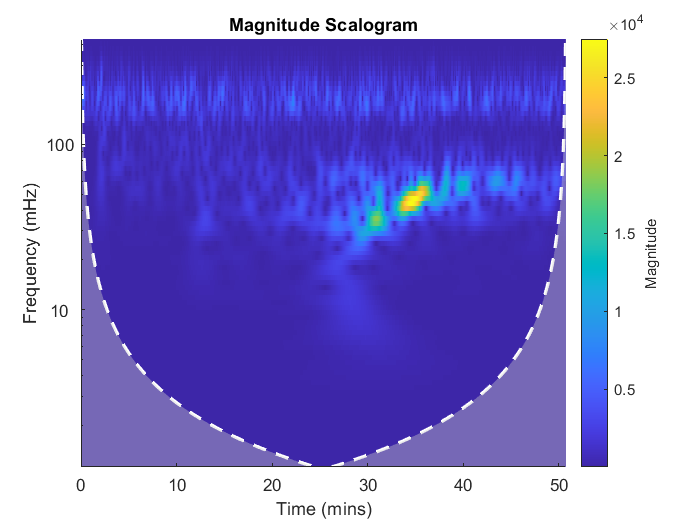

figure;
cwt(kobe,Fs);

### Более точный анализ

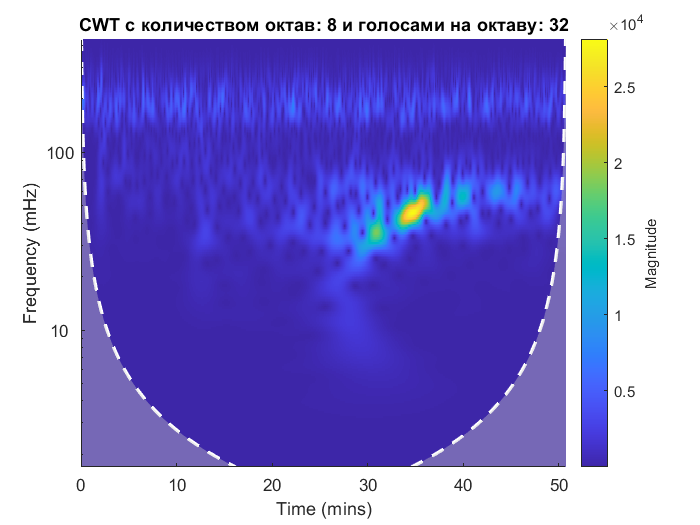

No = 8;
Nv = 32;
figure;
cwt(kobe,Fs, 'NumOctaves' ,No,'VoicesPerOctave',Nv); 
title('CWT с количеством октав: 8 и голосами на октаву: 32');

### Реконструкция сигнала землетрясения

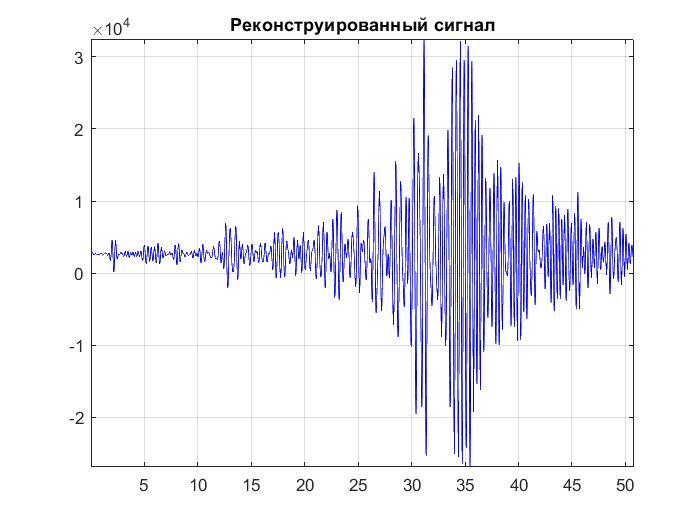

[WT, F] = cwt(kobe,Fs);
xrec = icwt(WT, F, [0.03 0.06],'SignalMean',mean(kobe));
figure;
plot(t,xrec,'b');title('Реконструированный сигнал');
axis tight;grid;